%FO8
clc
clear all
close all
% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
inf_wpts_zy = [1 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
inf_wpts_xy = [0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0 2 4 6 8 6 4 2 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0];
% tpts = 0:5;
inf_tpts = 0:sqrt(8):sqrt(8)*8*4;

numsamples = 100*4;

[inf_xy,inf_xyd,inf_xydd,inf_xyddd,inf_xydddd,inf_xypp,inf_xytimepoints,inf_xytsamples] = minsnappolytraj(inf_wpts_xy,inf_tpts,numsamples);
[inf_zy,inf_zyd,inf_zydd,inf_zyddd,inf_zydddd,inf_zypp,inf_zytimepoints,inf_zytsamples] = minsnappolytraj(inf_wpts_zy,inf_tpts,numsamples);

inf_final_pose = zeros(2,200);
inf_final_vel = zeros(2,200);
inf_final_acc = zeros(2,200);
inf_final_jerk = zeros(2,200);
inf_final_snap = zeros(2,200);

inf_final_z_pose = inf_zy(1,101:300);
inf_final_z_vel = inf_zyd(1,101:300);
inf_final_z_acc = inf_zydd(1,101:300);
inf_final_z_jerk = inf_zyddd(1,101:300);
inf_final_z_snap = inf_zydddd(1,101:300);

for v = 1:2
    inf_final_pose(v,:) = inf_xy(v,101:300);
    inf_final_vel(v,:) = inf_xyd(v,101:300);
    inf_final_acc(v,:) = inf_xydd(v,101:300);
    inf_final_jerk(v,:) = inf_xyddd(v,101:300);
    inf_final_snap(v,:) = inf_xydddd(v,101:300);
end

%plot(tsamples,q);
%plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
%python
%disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

%hold on
%plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
plot(inf_zytsamples(1,101:300), inf_final_pose(2,:))
xlabel('Time');
ylabel('Y-Positions');
% subplot(3,1,2) 
plot(inf_final_pose(1,:), inf_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
% grid
% 
% subplot(3,1,3)

plot3(inf_final_pose(1,:), inf_final_pose(2,:), inf_final_z_pose, "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
% %legend('X-positions','Y-positions')

%straight line
clc
clear all
close all
r=1; % radius
[c,x,y] = circle(-2,2,r);
x = x*-1;
y = x;
mm = sqrt(x.^2 + y.^2)
z = [1,1.5,2,1.5,1,1.5,2,1.5,1]
% y = y*-1;
disp (size(x));
disp ((x));
disp ((y));


% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
circle_wpts_xy = [mm mm(:,2:end) mm(:,2:end) mm(:,2:end); z z(:,2:end) z(:,2:end) z(:,2:end)]; % repeats for 4 times to ensure smoothness but we only take the middle points
% tpts = 0:5;

speed = 1; % 1 m/s = 1 rad/s based on v = r*omega 
sample_per_loop = 100;
time_per_setpt = ((sqrt(2) * 4) / sample_per_loop)/speed
total_time = time_per_setpt * 100;
 

% 1 m/s = (pi/4) / (1 rad/s) = pi/4
% 2 m/s = (pi/4) / (2 rad/s) = pi/8
% 3 m/s = (pi/4) / (3 rad/s) = pi/12
% 4 m/s = (pi/4) / (4 rad/s) = pi/16

circle_tpts = 0:total_time/8:total_time*4 % intervals @ 1 m/s = 1 rad/s based on v = r*omega


numsamples = sample_per_loop * 4;

[circle_xy,circle_xyd,circle_xydd,circle_xyddd,circle_xydddd,circle_xypp,circle_xytimepoints,circle_xytsamples] = minsnappolytraj(circle_wpts_xy,circle_tpts,numsamples);
%[zy,zyd,zydd,zyddd,zydddd,zypp,zytimepoints,zytsamples] = minsnappolytraj(wpts_zy,tpts,numsamples);

circle_final_pose = zeros(2,201);
circle_final_vel = zeros(2,201);
circle_final_acc = zeros(2,201);
circle_final_jerk = zeros(2,201);
circle_final_snap = zeros(2,201);

% final_z_pose = zy(1,101:300);
% final_z_vel = zyd(1,101:300);
% final_z_acc = zydd(1,101:300);
% final_z_jerk = zyddd(1,101:300);
% final_z_snap = zydddd(1,101:300);

for v = 1:2
    circle_final_pose(v,:) = circle_xy(v,101:301);
    circle_final_vel(v,:) = circle_xyd(v,101:301);
    circle_final_acc(v,:) = circle_xydd(v,101:301);
    circle_final_jerk(v,:) = circle_xyddd(v,101:301);
    circle_final_snap(v,:) = circle_xydddd(v,101:301);
end

% because the above solution starts from the same point but moves in a
% clockwise fashion as compared to what I wanted which was anti-clockwise
% from the same starting pt

invert_pos = zeros(2,201);
invert_pos(2,:) = (circle_final_pose(2,:));
invert_pos(1,:) = flip(circle_final_pose(1,:));

invert_vel = zeros(2,201);
invert_vel(2,:) = (circle_final_vel(2,:));
invert_vel(1,:) = (circle_final_vel(1,:));

invert_acc = zeros(2,201);
invert_acc(2,:) = (circle_final_acc(2,:));
invert_acc(1,:) = (circle_final_acc(1,:));

invert_jer = zeros(2,201);
invert_jer(2,:) = (circle_final_jerk(2,:));
invert_jer(1,:) = (circle_final_jerk(1,:));

invert_sna = zeros(2,201);
invert_sna(2,:) = (circle_final_snap(2,:));
invert_sna(1,:) = (circle_final_snap(1,:));

diff_pos = zeros(2,200); 
diff_vel = zeros(2,200);
diff_acc = zeros(2,200);

% used in the later parts
diff_jer = zeros(2,200);
diff_sna = zeros(2,200);

for v = 1:2
    for i = 1:200
        diff_pos(v,i) = invert_pos(v,i+1) - invert_pos(v,i); 
        diff_vel(v,i) = invert_vel(v,i+1) - invert_vel(v,i); 
        diff_acc(v,i) = invert_acc(v,i+1) - invert_acc(v,i); 
        diff_jer(v,i) = invert_jer(v,i+1) - invert_jer(v,i); 
        diff_sna(v,i) = invert_sna(v,i+1) - invert_sna(v,i); 
    end
end

mag = zeros(5,200);

mag(1,:) = sqrt((diff_pos(1,:)).^2 + (diff_pos(2,:)).^2);
mag(2,:) = sqrt((diff_vel(1,:)).^2 + (diff_vel(2,:)).^2);
mag(3,:) = sqrt((diff_acc(1,:)).^2 + (diff_acc(2,:)).^2);
mag(4,:) = sqrt((diff_jer(1,:)).^2 + (diff_jer(2,:)).^2);
mag(5,:) = sqrt((diff_sna(1,:)).^2 + (diff_sna(2,:)).^2);

direction = atan2(diff_pos(2,:),diff_pos(1,:));
direction_deg = rad2deg(direction);



% direction = atan2(circle_final_pose(1,:),circle_final_pose(2,:));

% direction_deg = rad2deg(atan2(diff_y(:,26:50),diff_x(:,26:50)));
% direction = atan2(diff_y(:,1:25),diff_x(:,1:25));
% polarplot(direction,mag(:,1:25));


polarplot(direction,mag(1,:));


% plot(tsamples,q);
% plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
% python
% disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

% hold on
% plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(circle_final_pose(1,:), circle_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
% grid
% 
% subplot(3,1,3)
z = zeros([size(circle_final_pose(1,:))]);
plot3(circle_final_pose(1,:), z, circle_final_pose(2,:), "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
% %legend('X-positions','Y-positions')


%CIRCLE
clc
clear all
close all
r=1; % radius
[c,x,y] = circle(-2,2,r);
x = x*-1;
y = x;
mm = sqrt(x.^2 + y.^2)
z = [1,1.25,1.5,1.75,2,1.75,1.5,1.25,1]
% y = y*-1;
disp (size(x));
disp ((x));
disp ((y));


% wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
%wpts_zy = [0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0 0.5 1.0 0.5 0; 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0 -2 0 2 0]; 
circle_wpts_xy = [x x(:,2:end) x(:,2:end) x(:,2:end); y y(:,2:end) y(:,2:end) y(:,2:end)]; % repeats for 4 times to ensure smoothness but we only take the middle points
% tpts = 0:5;

speed = 1; % 1 m/s = 1 rad/s based on v = r*omega
time_per_eigth = (pi/4)/speed; 
sample_per_loop = 100;
time_per_setpt = (time_per_eigth * 8) / sample_per_loop; 

% 1 m/s = (pi/4) / (1 rad/s) = pi/4
% 2 m/s = (pi/4) / (2 rad/s) = pi/8
% 3 m/s = (pi/4) / (3 rad/s) = pi/12
% 4 m/s = (pi/4) / (4 rad/s) = pi/16

circle_tpts = 0:time_per_eigth:time_per_eigth*8*4; % intervals @ 1 m/s = 1 rad/s based on v = r*omega

numsamples = sample_per_loop * 4;

[circle_xy,circle_xyd,circle_xydd,circle_xyddd,circle_xydddd,circle_xypp,circle_xytimepoints,circle_xytsamples] = minsnappolytraj(circle_wpts_xy,circle_tpts,numsamples);
%[zy,zyd,zydd,zyddd,zydddd,zypp,zytimepoints,zytsamples] = minsnappolytraj(wpts_zy,tpts,numsamples);

circle_final_pose = zeros(2,201);
circle_final_vel = zeros(2,201);
circle_final_acc = zeros(2,201);
circle_final_jerk = zeros(2,201);
circle_final_snap = zeros(2,201);

% final_z_pose = zy(1,101:300);
% final_z_vel = zyd(1,101:300);
% final_z_acc = zydd(1,101:300);
% final_z_jerk = zyddd(1,101:300);
% final_z_snap = zydddd(1,101:300);

for v = 1:2
    circle_final_pose(v,:) = circle_xy(v,101:301);
    circle_final_vel(v,:) = circle_xyd(v,101:301);
    circle_final_acc(v,:) = circle_xydd(v,101:301);
    circle_final_jerk(v,:) = circle_xyddd(v,101:301);
    circle_final_snap(v,:) = circle_xydddd(v,101:301);
end

% because the above solution starts from the same point but moves in a
% clockwise fashion as compared to what I wanted which was anti-clockwise
% from the same starting pt

invert_pos = zeros(2,201);
invert_pos(2,:) = (circle_final_pose(2,:));
invert_pos(1,:) = flip(circle_final_pose(1,:));

invert_vel = zeros(2,201);
invert_vel(2,:) = (circle_final_vel(2,:));
invert_vel(1,:) = (circle_final_vel(1,:));

invert_acc = zeros(2,201);
invert_acc(2,:) = (circle_final_acc(2,:));
invert_acc(1,:) = (circle_final_acc(1,:));

invert_jer = zeros(2,201);
invert_jer(2,:) = (circle_final_jerk(2,:));
invert_jer(1,:) = (circle_final_jerk(1,:));

invert_sna = zeros(2,201);
invert_sna(2,:) = (circle_final_snap(2,:));
invert_sna(1,:) = (circle_final_snap(1,:));

diff_pos = zeros(2,200); 
diff_vel = zeros(2,200);
diff_acc = zeros(2,200);

% used in the later parts
diff_jer = zeros(2,200);
diff_sna = zeros(2,200);

for v = 1:2
    for i = 1:200
        diff_pos(v,i) = invert_pos(v,i+1) - invert_pos(v,i); 
        diff_vel(v,i) = invert_vel(v,i+1) - invert_vel(v,i); 
        diff_acc(v,i) = invert_acc(v,i+1) - invert_acc(v,i); 
        diff_jer(v,i) = invert_jer(v,i+1) - invert_jer(v,i); 
        diff_sna(v,i) = invert_sna(v,i+1) - invert_sna(v,i); 
    end
end

mag = zeros(5,200);

mag(1,:) = sqrt((diff_pos(1,:)).^2 + (diff_pos(2,:)).^2);
mag(2,:) = sqrt((diff_vel(1,:)).^2 + (diff_vel(2,:)).^2);
mag(3,:) = sqrt((diff_acc(1,:)).^2 + (diff_acc(2,:)).^2);
mag(4,:) = sqrt((diff_jer(1,:)).^2 + (diff_jer(2,:)).^2);
mag(5,:) = sqrt((diff_sna(1,:)).^2 + (diff_sna(2,:)).^2);

direction = atan2(diff_pos(2,:),diff_pos(1,:));
direction_deg = rad2deg(direction);



% direction = atan2(circle_final_pose(1,:),circle_final_pose(2,:));

% direction_deg = rad2deg(atan2(diff_y(:,26:50),diff_x(:,26:50)));
% direction = atan2(diff_y(:,1:25),diff_x(:,1:25));
% polarplot(direction,mag(:,1:25));


polarplot(direction,mag(1,:));


% plot(tsamples,q);
% plot(tsamples,q(1,:)) % matlab rows and cols start with 1 and not 0 unlike
% python
% disp (timepoints); % produces the m x n which is the rows and columns respectively of the matrix 

% hold on
% plot(timepoints,wpts,'x')

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(circle_final_pose(1,:), circle_final_pose(2,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal
% grid
% 
% subplot(3,1,3)
z = ones([size(circle_final_pose(1,:))]);
plot3(circle_final_pose(1,:), circle_final_pose(2,:), z, "red",'LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')
axis equal
% %legend('X-positions','Y-positions')

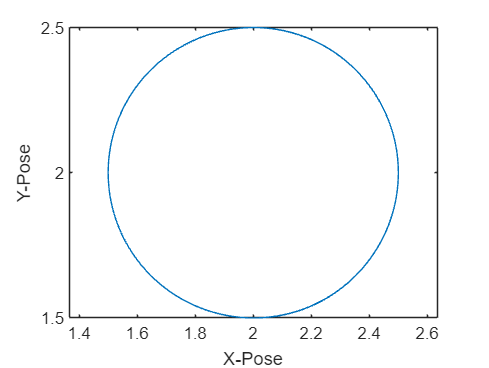

% testing the classes

% aux = ExpAuxiliaryFunctions;
% y = aux.quadrant_output(-2.356)
% C1 = aux.circle_setpoints_anti_cw(1,2,2,1)
% C = aux.circle_setpoints_cw(1,-2,2,1)
clc
clear all
test = test_ExpAuxiliaryFunctions;
C3 = test.circle_setpoints_anti_cw(1,2.0,2.0,0.5,300); % comparing against this 
diff_flat = zeros(8,C3(10,2));
col_size = C3(10,2);
%C3 = flip(C3,2); % circle goes the other way, proved that the rotation direction can improve or impede the linear acceleration
%actuation_angles = zeros(178,3,361); % the last axis is the layer
actuation_angles = zeros(360,179);
i = 2;
c = 1;
%p = -180;

for p = -180:179
    k = deg2rad(p); % desired heading
    actuation_angles(c,1) = p;
    for v = -180:180
        a = deg2rad(v); % azimuth
        quad = test.quadrant_output(k);
        flap = abs(test.flap_output(a,quad,k,-1));
        if flap(:,1) > 0
            actuation_angles(c,i) = v; % azimuth w abs(flap) > 1
            i = i+1;
        end
    end 
    i = 2;
    c = c+1;
end


% diff flat is defined on top
drag = [0,0,0];
pitch = 41; % degrees
rotation_dir = -1; 
% 1 represents ccw which means z vector faces up  
% -1 represents cw which means z vector faces down  
for i = 1:col_size
    vel = [C3(14,i),C3(15,i),C3(16,i)];
    acc = [C3(17,i),C3(18,i),C3(19,i)];
    jer = [C3(20,i),C3(21,i),C3(22,i)];
    sna = [C3(23,i),C3(24,i),C3(25,i)];
    diff_flat(:,i) = transpose(test.diff_flat(pitch,drag,vel,acc,jer,sna,"circle",rotation_dir));
end

figure(1)
% subplot(3,1,1) 
% plot(zytsamples(1,101:300), final_pose(2,:))
% xlabel('Time');
% ylabel('Y-Positions');
% subplot(3,1,2) 
plot(C3(11,:), C3(12,:))
xlabel('X-Pose')
ylabel('Y-Pose')
axis equal

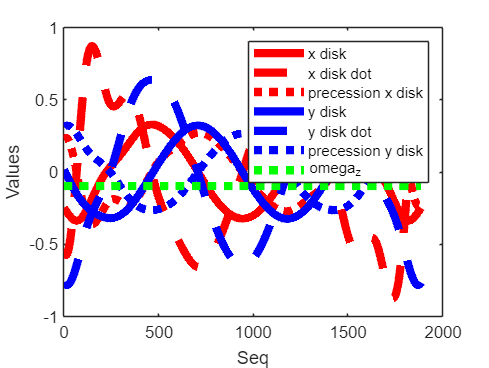




A = C3(26,:); % rad/s
threshold = [1 99];
desired_precession = transpose(rmoutliers(A,"percentiles",threshold));
p_size = size(desired_precession);
desired_acc = transpose(C3(18,1:p_size(1,1))); % y acc
%fprintf('Desired precession (%d) vs desired acc (%d)', B, counter_actl);
%plot(1:p_size(1,1),desired_precession)
% hold on
% plot(1:p_size(1,1),desired_acc,'Color','red')
%xlabel('Seq')
%ylabel('Values')
% legend('desired precession','desired acc')
% hold off

% f = fitlm(desired_acc,desired_precession) % acc precession function
% linear_p = 0.0014513 + 114.62*(desired_acc);
% plot(desired_acc,linear_p);


plot(1:col_size,diff_flat(1,:),'Color','red','linewidth',5)
hold on
plot(1:col_size,diff_flat(3,:),'Color','red','lineStyle','--','linewidth',5)
plot(1:col_size,diff_flat(5,:),'Color','red','lineStyle',':','linewidth',5)
plot(1:col_size,diff_flat(2,:),'Color','blue','linewidth',5)
plot(1:col_size,diff_flat(4,:),'Color','blue','lineStyle','--','linewidth',5)
plot(1:col_size,diff_flat(6,:),'Color','blue','lineStyle',':','linewidth',5)
plot(1:col_size,diff_flat(8,:)/100,'Color','green','lineStyle',':','linewidth',5)
%plot(1:1886,diff_flat(7,:),'Color','green','linewidth',5)
xlabel('Seq')
ylabel('Values')
legend('x disk','x disk dot','precession x disk','y disk','y disk dot','precession y disk','omega_z')
hold off


current_location = [2.5,2.0,1.0];
desired_location = [2.0,1.5,1.0];
kp = 0.5;
error = kp*(desired_location - current_location);
mea_euler = [0,0,0];
test.test_attitude(mea_euler,error)

ans =     0.5000   -0.5000


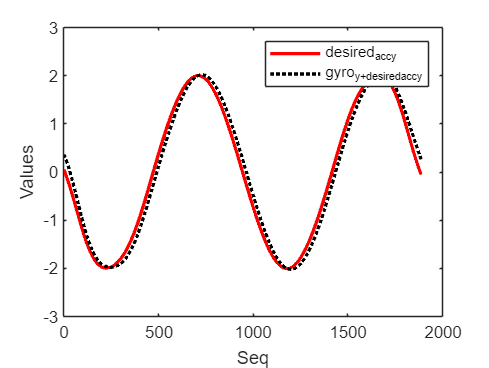


acc_x = C3(17,:);
acc_y = C3(18,:);
gyro_x = diff_flat(5,:);
gyro_y = diff_flat(6,:);
total_gyro = gyro_x+gyro_y;

plot(1:col_size,acc_y,'Color','red','linewidth',2)
%plot(1:col_size,gyro_x+gyro_y,'Color','red','linewidth',2)
% dp = transpose(desired_precession);
% plot(1:p_size(1,1),dp(1:p_size(1,1)),'Color','red','linewidth',2)
hold on
%plot(1:col_size,acc_y,'Color','blue','linewidth',2)
%plot(1:p_size(1,1),dp(1:p_size(1,1)) - total_gyro(1:p_size(1,1)),'Color','black','lineStyle',':','linewidth',2)
plot(1:col_size,acc_y+gyro_y,'Color','black','lineStyle',':','linewidth',2)

% plot(1:100,desired_precession-(total_gyro(1:1:p_size(1,1))),'Color','blue','linewidth',2)
xlabel('Seq')
ylabel('Values')
legend('desired_acc_y','gyro_y+desired_acc_y')
% legend('dp','dp+gyro')
% legend('gyro_x+gyro_y','pref-(gyro_x+gyro_y)')
hold off

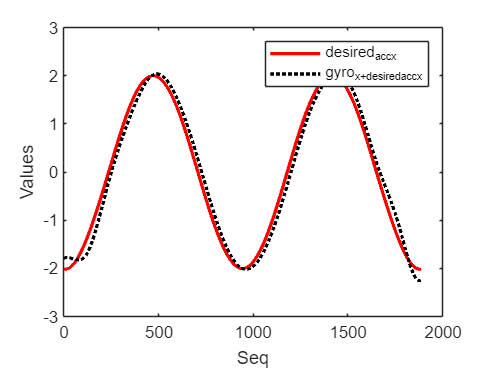

%ylim([1.9 2.15]) % compute error to say residual gyroscopic effects are negligible 

plot(1:col_size,acc_x,'Color','red','linewidth',2)
hold on
plot(1:col_size,acc_x+gyro_x,'Color','black','lineStyle',':','linewidth',2)
xlabel('Seq')
ylabel('Values')
legend('desired_acc_x','gyro_x+desired_acc_x')
hold off









theta = 20;
phi = -20; % roll
theta = 2; % pitch 
v = [4000;-1000;-1440];

W = [ 1,  0,        -sin(theta);
          0,  cos(phi),  cos(theta)*sin(phi);
          0, -sin(phi),  cos(theta)*cos(phi) ];


clc
clear all
close all
[c,x,y] = circle(0,0,1);
disp (size(x));

% Specify waypoints, times of arrival, and sampling rate. 
wp = [0 0 0; 2 -2 0; 4 0 0; 6 2 0; 8 0 0; 6 -2 0; 4 0 0; 2 2 0; 0 0 0];
toa = sqrt(8)*(0:size(wp,1)-1).'
vel = [0 0 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 1 1 0; 0 0 0];
Fs = 100; % resolution

% Create trajectory. 
traj = waypointTrajectory(wp, toa, SampleRate=Fs, ReferenceFrame='ENU')
disp (traj.Velocities);
% Get position.
t = 0:1/Fs:traj.TimeOfArrival(end);
pos = lookupPose(traj, t);
size(pos)

figure(1)
subplot(2,1,1) 
plot(t,pos(:,2))
xlabel('t');
ylabel('Y-Positions');
subplot(2,1,2) 
plot(pos(:,1),pos(:,2))
xlabel('X-Pose')
ylabel('Y-Pose')

function [overall,xunit,yunit] = circle(x,y,r)
% hold on
x_origin = x;
y_origin = y;
radius = r;
%th = 0:pi/50:2*pi; % 100 pts
th = 0:pi/4:2*pi; % 8 pts
xunit = radius * cos(th) + x_origin;
yunit = radius * sin(th) + y_origin;
z = ones([size(xunit)]);
overall = plot3(xunit, yunit, z, "red",'LineWidth',5);
xlabel('X')
ylabel('Y')
ylabel('Z')
%axis equal
% hold off
end


